# API from the ground up

### This is a guide for

- creating asset types (component types), assets (components), component models, and UAVs

- loading component models and UAVs

- Performing a simulation with a UAV (choose a random trajectory and fly it)

- Plotting telemetry & powertrain data from the simulation

- displaying summary statistics 

### (Preliminary) Connect to database

- To configure the data source, see [https://www.mathworks.com/help/database/ug/configuring-driver-and-data-source.html](https://www.mathworks.com/help/database/ug/configuring-driver-and-data-source.html) 

- go to System DSN, Add, select PostgreSQL ANSI(x64), set the datasource name = uav_db, fill out the rest of the fields and test the connection

% ensures that matlab can find everything 
addpath(genpath(pwd));

% these is a separate file that loads the connection parameters for the database
% i.e. 'database_name', 'datasource_name', 'host_name', 'user_name', 'password'
load_db_params;

% the database connection
conn = database(datasource_name, user_name, password)
% clear the database connection parameters from the workspace
clear('database_name', 'datasource_name', 'host_name', 'user_name', 'password');

## 1. Creating asset types, assets, component models, and UAVs

- assets are the underlying model that all components inherit from and are created indirectly when a component is created

### Create an asset type

%asset_type = create_asset_type(conn, "airframe", "default", "osmic_2016")

### Create an airframe

- an airframe is an asset, which is an object type that underlies all components

- note - move airframe sample time (.025)

owner         = "darrahts";

conn =   connection with properties:

                  DataSource: 'uav_db'
                    UserName: 'tsdbadmin'
                     Message: ''
                        Type: 'ODBC Connection Object'
  Database Properties:

                  AutoCommit: 'on'
                    ReadOnly: 'off'
                LoginTimeout: 0
      MaxDatabaseConnections: 0

  Catalog and Schema Information:

              DefaultCatalog: 'tsdb'
                    Catalogs: {'tsdb'}
                     Schemas: {'_timescaledb_cache', '_timescaledb_catalog', '_timescaledb_config' ... and 5 more}

  Database and Driver Information:

         DatabaseProductName: 'PostgreSQL'
      DatabaseProductVersion: '12.0.6'
                  DriverName: 'PSQLODBC30A.DLL'
               DriverVersion: '13.00.0000'


type_id       = asset_type.id;
serial_number = sprintf("x%06d", 1);
num_motors    = 8;
age           = 0;
units         = "flight hours";

airframe = create_default_airframe(conn, ...

asset_type = struct with fields:
             id: 1
           type: 'airframe'
        subtype: 'octorotor'
    description: 'osmic_2016'


                                   owner, ...
                                   type_id, ...
                                   serial_number, ...
                                   num_motors, ...
                                   age, ...
                                   units)

### Create the motors

- dont forget to create an asset type if it is not already created

asset_type = create_asset_type(conn, "motor", "dc", "darrah_2020")
owner      = "darrahts";
type_id    = asset_type.id;
age        = 0;
units      = "flight hours";

% there are multiple motors
for i=1:airframe.num_motors
    serial_number = sprintf("m%06d", i);
    motor = create_default_motor(conn, ...

airframe = struct with fields:
            id: 1
    num_motors: 8
            ct: 8.5486e-06
            cq: 1.3678e-07
          mass: 1.8000
            Jb: '{0.0429,0,0,0,0.0429,0,0,0,0.0748}'
            cd: 1
           Axy: 0.0400
           Axz: 0.0400
           Ayz: 0.0400
           rho: 1.2000
            lx: 0.2000
            ly: 0.2000
            lz: 0.2000
             l: 0.4500


                                 owner, ...
                                 type_id, ...
                                 serial_number, ...

asset_type = struct with fields:
             id: 2
           type: 'motor'
        subtype: 'dc'
    description: 'darrah_2020'


                                 age, ... 
                                 units);
   motors.(sprintf("motor_%d", i)) = motor;
end 
motor 

### Create the battery (cell)

- the default battery model is a single cell, so to better model battery pack behavior one must create multiple cells and then wire them manually

asset_type = create_asset_type(conn, "battery", "discrete-eqc", "plett_2015")
owner         = "darrahts";
type_id       = asset_type.id;
serial_number = sprintf("b%06d", 1);
age           = 0;
units         = "cumulative amp hours";

battery = create_default_battery(conn, ...
                                 owner, ...
                                 type_id, ...
                                 serial_number, ...

motor = struct with fields:
              id: 9
    motor_number: NaN
             Req: 0.2371
           Ke_eq: 0.0107
               J: 2.0000e-05
              Df: 0
              cq: 1.3678e-07


                                 age, ...
                                 units)

### Create the UAV

asset_type = create_asset_type(conn, "uav", "octo", "cube")

asset_type = struct with fields:
             id: 3
           type: 'battery'
        subtype: 'discrete-eqc'
    description: 'plett_2015'


owner         = "darrahts";
type_id       = asset_type.id;
serial_number = sprintf("u%06d", 1);
age           = 0;
units         = "flight hours";

uav = create_default_uav(conn, ...
                         owner, ...
                         type_id, ...
                         serial_number, ...
                         age, ...
                         units, ...

battery = struct with fields:
        id: 10
    cycles: 0
         Q: 15
         G: 163.4413
         M: 0.0092
        M0: 0.0019
        RC: 3.6572
         R: 2.8283e-04
        R0: -0.0011
         n: 0.9987
       EOD: 3.0400
         z: 1
        Ir: 0
         h: 0
         v: 4.2000
        v0: 4.2000
        dt: 1


                         airframe, ...
                         battery, ...

asset_type = struct with fields:
             id: 4
           type: 'uav'
        subtype: 'octo'
    description: 'cube'


                         motors)

## 2. Loading components and the UAV 

#### by serial number which contains the IDs of the components for this specific UAV

serial_number = 'u000001';
uav = load_uav(conn, serial_number)
uav.uav
uav.battery
uav.airframe
uav.motors

uav = struct with fields:
                 id: 11
           airframe: [1×1 struct]
            battery: [1×1 struct]
             motors: [1×1 struct]
    max_flight_time: 18


## Data retrieval

### Get a list of UAVs

statement = "select count(fst.*) as num_flights, fst.uav_id, ast.serial_number from flight_summary_tb fst join asset_tb ast on fst.uav_id = ast.id group by fst.uav_id, ast.serial_number order by fst.uav_id asc;";
res = select(conn, statement);

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
             motors: [8×1 struct]
    max_flight_time: 18
                 id: 11
               mass: 1.8000


res = res(res.num_flights < 200, :)

ans = struct with fields:
                 id: 11
              owner: 'darrahts'
            type_id: 4
      serial_number: 'u000001'
                age: 0
                eol: NaN
              units: 'flight hours'
               id_1: 11
        airframe_id: 1
         battery_id: 10
          motor1_id: 2
          motor2_id: 3
          motor3_id: 4
          motor4_id: 5
          motor5_id: 6
          motor6_id: 7
          motor7_id: 8
          motor8_id: 9
    max_flight_time: 18


uav_ids = res.uav_id(:);

ans = struct with fields:
         id: 10
     cycles: 0
          Q: 15
          G: 163.4413
          M: 0.0092
         M0: 0.0019
         RC: 3.6572
          R: 2.8283e-04
         R0: 0.0011
          n: 0.9987
        EOD: 3.0400
          z: 1
         Ir: 0
          h: 0
          v: 4.2000
         v0: 4.2000
         dt: 1
    soc_ocv: [1×101 double]


uav_serial_numbers = res.serial_number(:);

ans = struct with fields:
            id: 1
    num_motors: 8
            ct: 8.5486e-06
            cq: 1.3678e-07
          mass: 1.8000
            Jb: [3×3 double]
            cd: 1
           Axy: 0.0400
           Axz: 0.0400
           Ayz: 0.0400
           rho: 1.2000
            lx: 0.2000
            ly: 0.2000
            lz: 0.2000
             l: 0.4500


f1 = figure(1); clf;

ans = 8×1 struct array with fields:
    id
    owner
    type_id
    serial_number
    age
    eol
    units
    id_1
    motor_number
    Req
    Ke_eq
    J
    Df
    cq


bar(res.uav_id, res.num_flights);
xtickangle(45);
title("Number of flights before failure");
ylabel("Flight Number");
xlabel("UAV ID");

### Look at flight summary and degradation data for a given UAV

uav_idx = 2;

res = 15×3 table
    num_flights    uav_id    serial_number
    ___________    ______    _____________

        84           70       {'u000111'} 
        84           81       {'u000112'} 
        83           92       {'u000113'} 
        82          103       {'u000114'} 
        84          114       {'u000115'} 
        86          137       {'u000116'} 
        85          148       {'u000117'} 
        85          159       {'u000118'} 
        85          170       {'u000119'} 
        24          181       {'u000120'} 
        80          192       {'u000151'} 
        80          203       {'u000152'} 
        80          214       {'u000153'} 
        79          225       {'u000154'} 
        78          236       {'u000155'} 


uav_id = uav_ids(uav_idx)
uav_serial_number = string(uav_serial_numbers(uav_idx))
statement = sprintf("select fst.*, fdt.* from flight_summary_tb fst join flight_degradation_tb fdt on fst.id = fdt.flight_id where fst.uav_id = %d;", uav_id);
res = select(conn, statement)

### Plot the system performance parameters

- z_end (state of charge)

- v_end (output voltage)

- avg_pos_err (average position error over the entire flight)

- std_pos_err (standard deviation of the position error of an entire flight)

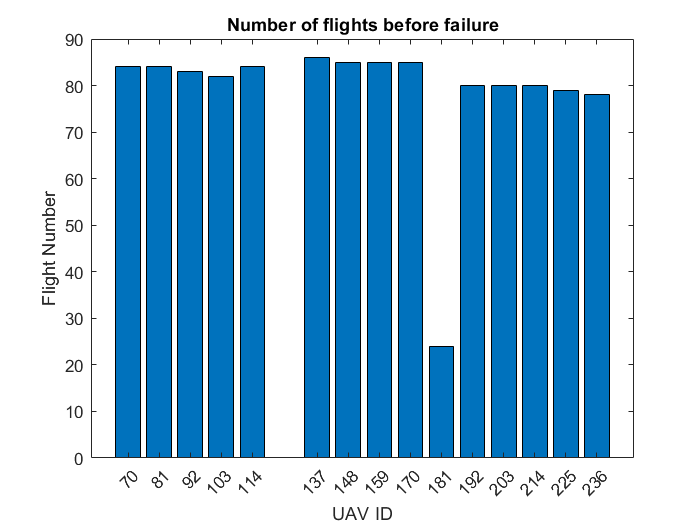

f2 = figure(2); clf;
f2.Position = [0 0 900 500];
subplot(2,2,1);
plot(res.z_end)

title("State of Charge Degradation")
ylabel("SOC (%)")
xlabel("Flight Number")


uav_id = int32
81

subplot(2,2,2);

uav_serial_number = "u000112"

plot(res.v_end);
title("Output Voltage Degradation")

res = 84×34 table
    id     stop_code     z_end     v_end     avg_pos_err    max_pos_err    std_pos_err    avg_ctrl_err    max_ctrl_err    std_ctrl_err    distance    flight_time    avg_current    amp_hours           dt_start                    dt_stop            trajectory_id    uav_id    flight_num    id_1    flight_id    q_deg     q_var     q_slope     q_intercept      r_deg        r_var       r_slope      r_intercept     m_deg     m_var     m_slope

ylabel("(v)")
xlabel("Flight Number")

subplot(2,2,3);
plot(res.avg_pos_err);
title("Position Error (mean)")
ylabel("(m)")
xlabel("Flight Number")
ylim([1.2 1.3]);

subplot(2,2,4);
plot(res.std_pos_err);
title("Position Error (std)")
ylabel("(m)")
xlabel("Flight Number")
ylim([.6 .7]);

### Plot component degradation parameters

- q_deg (battery capacitance)

- r_deg (battery internal resistance)

- m_deg (motor resistance)

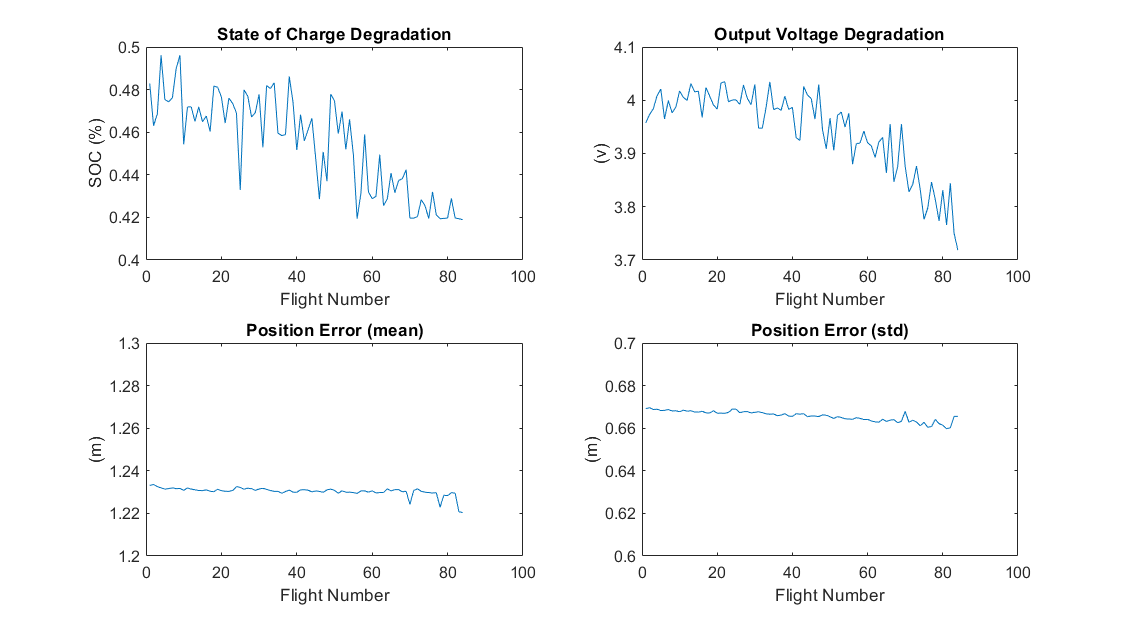

f3 = figure(3); clf;
f3.Position = [0 0 900 200];
subplot(1,3,1);
plot(res.q_deg)
title("Battery Charge Capacitance")
ylabel("Capacitance (A)")
xlabel("Flight Number")

subplot(1,3,2);
plot(res.r_deg);
title("Battery Internal Resistance")
ylabel("(Ohms)")
xlabel("Flight Number")


subplot(1,3,3);
plot(res.m_deg);
title("Motor Resistance")
ylabel("(Ohms)")
xlabel("Flight Number")

### Perform a simulation with a UAV

%% see example.mlx

### Plot telemetry data from a single flight

statement = "select fst.*, fdt.* from flight_summary_tb fst join flight_degradation_tb fdt on fst.id = fdt.flight_id where fst.uav_id >69 order by fst.uav_id asc;";
res = select(conn, statement)

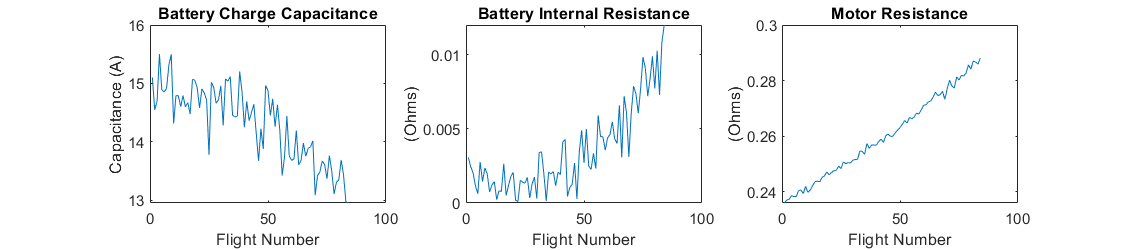

res = 1179×34 table
    id     stop_code     z_end     v_end     avg_pos_err    max_pos_err    std_pos_err    avg_ctrl_err    max_ctrl_err    std_ctrl_err    distance    flight_time    avg_current    amp_hours           dt_start                    dt_stop            trajectory_id    uav_id    flight_num    id_1    flight_id    q_deg     q_var     q_slope      q_intercept      r_deg        r_var       r_slope      r_intercept     m_deg     m_var     m_slope